% DIGITAL SIGNAL PROCESSING LAB
% Experiment No. - 4
% Name: Aditya Sinha
% PRN: 24070123006
%
% ECG FILTERING: LINEAR AND CIRCULAR CONVOLUTION
% MATLAB R2026a 
%
% Healthcare application:
% Comparison of linear and circular convolution in ECG filtering using 
% MIT-BIH Arrhythmia Database Record 114.
%
% x[n] = Raw Noisy ECG signal
% h[n] = 15-sample moving-average FIR filter
%
% Linear convolution preserves the actual ECG time sequence.
% Circular convolution may wrap the ending samples to the beginning.

clc;
clear;
close all;


## 1. READ THE MIT-BIH RECORD 114 DATASET (.dat binary file)

filename = './dat/114.dat';
fid = fopen(filename, 'r');
if fid == -1
    error('Cannot open file %s. Ensure it is in the ./dat/ directory.', filename);
end

% Read the binary data as 8-bit unsigned integers
A = fread(fid, [3, inf], 'uint8');
fclose(fid);

% Decode Format 212
M1H = bitand(A(2,:), 15);        % High nibble of channel 1
M2H = bitshift(A(2,:), -4);      % High nibble of channel 2

sig1 = bitshift(M1H, 8) + A(1,:);
sig2 = bitshift(M2H, 8) + A(3,:);

% Convert to signed 12-bit integers
sig1(sig1 > 2047) = sig1(sig1 > 2047) - 4096;
sig2(sig2 > 2047) = sig2(sig2 > 2047) - 4096;

% Channel 2 (MLII) used as primary ECG signal
ecg_raw = sig2(:);


## 2. EXTRACT A FINITE BLOCK FOR CONVOLUTION ANALYSIS

Fs = 360;                     % Sampling frequency (MIT-BIH standard)
duration = 6.6; % ECG duration in seconds (3 seconds)
N = Fs * duration;            % Number of samples (1080)

x = ecg_raw(1:N);             % Extract the finite block
t = (0:N-1) / Fs;             % Time vector


## 3. DEFINE FIR FILTER h[n]

M = 30;
h = ones(1,M)/M;


## 4. LINEAR CONVOLUTION

yLinearFull = conv(x, h, 'full');
tLinear = (0:length(yLinearFull)-1)/Fs;

% First N samples for comparison
yLinear = yLinearFull(1:N);
yLinear = yLinear(:);


## 5. CIRCULAR CONVOLUTION

% Ensure h is the same length as x by zero-padding for FFT
h_padded = [h(:); zeros(N-length(h), 1)];

yCircular = real(ifft(fft(x, N) .* fft(h_padded, N)));
yCircular = yCircular(:);


## 6. ZERO-PADDED FFT CONVOLUTION

Nfft = length(x) + length(h) - 1;

x_padded = [x(:); zeros(Nfft-length(x), 1)];
h_padded_full = [h(:); zeros(Nfft-length(h), 1)];

yFFTLinear = real(ifft(fft(x_padded, Nfft) .* fft(h_padded_full, Nfft)));


## 7. DISPLAY RESULTS

verificationError = max(abs(yLinearFull(:) - yFFTLinear(:)));
wrapError = yCircular - yLinear;

fprintf('\nECG CONVOLUTION ANALYSIS\n');


ECG CONVOLUTION ANALYSIS


fprintf('------------------------------------------\n');

------------------------------------------


fprintf('Number of ECG samples      = %d\n', N);

Number of ECG samples      = 2376


fprintf('Filter length              = %d\n', M);

Filter length              = 30


fprintf('Linear output length       = %d\n', length(yLinearFull));

Linear output length       = 2405


fprintf('Circular output length     = %d\n', length(yCircular));

Circular output length     = 2376


fprintf('Zero-padded FFT error      = %.12f\n', verificationError);

Zero-padded FFT error      = 0.000000000001


fprintf('Maximum wrap-around error  = %.6f\n', max(abs(wrapError)));

Maximum wrap-around error  = 1129.633333


## 8. PLOT THE RESULTS

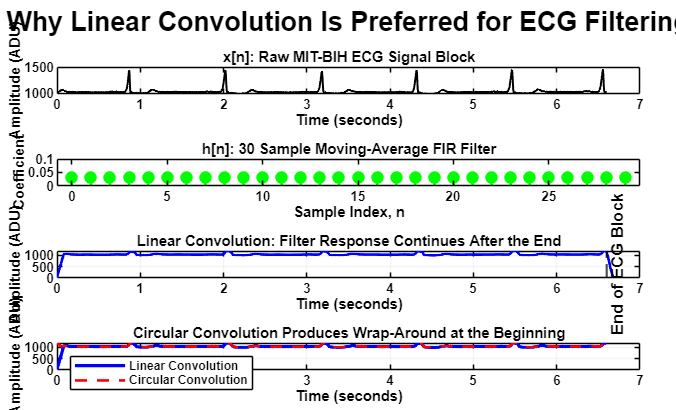

figure('Color','white', ...
       'Name','ECG Convolution Comparison', ...
       'NumberTitle','off', ...
       'Position',[80 40 1400 850]);

tiledlayout(4,1, ...
            'TileSpacing','compact', ...
            'Padding','compact');

% Plot 1: Raw ECG
nexttile;
plot(t, x, 'k', 'LineWidth', 1.2);
grid on; box on;
set(gca, 'Color','white', 'XColor','black', 'YColor','black', ...
    'GridColor',[0.75 0.75 0.75], 'FontWeight','bold');
xlabel('Time (seconds)','FontWeight','bold');
ylabel('Amplitude (ADU)','FontWeight','bold');
title('x[n]: Raw MIT-BIH ECG Signal Block', 'Color','black', 'FontWeight','bold');

% Plot 2: FIR filter h[n]
nexttile;
stem(0:M-1, h, 'g', 'filled', 'LineWidth', 1.5);
grid on; box on;
set(gca, 'Color','white', 'XColor','black', 'YColor','black', ...
    'GridColor',[0.75 0.75 0.75], 'FontWeight','bold');
xlabel('Sample Index, n','FontWeight','bold');
ylabel('Coefficient','FontWeight','bold');
title("h[n]: " + M + " Sample Moving-Average FIR Filter", ...
      'Color', 'black', ...
      'FontWeight', 'bold');
ylim([0 0.1]);

% Plot 3: Linear convolution
nexttile;
plot(tLinear, yLinearFull, 'b', 'LineWidth', 1.6);
hold on;
xline(duration, 'k--', 'End of ECG Block', 'LineWidth', 1.3, ...
      'FontWeight','bold', 'LabelVerticalAlignment','middle');
grid on; box on;
set(gca, 'Color','white', 'XColor','black', 'YColor','black', ...
    'GridColor',[0.75 0.75 0.75], 'FontWeight','bold');
xlabel('Time (seconds)','FontWeight','bold');
ylabel('Amplitude (ADU)','FontWeight','bold');
title('Linear Convolution: Filter Response Continues After the End', 'Color','black' ...
    , 'FontWeight','bold');

% Plot 4: Linear and circular comparison
nexttile;
p1 = plot(t, yLinear, 'b', 'LineWidth', 2);
hold on;
p2 = plot(t, yCircular, 'r--', 'LineWidth', 1.6);
grid on; box on;
set(gca, 'Color','white', 'XColor','black', 'YColor','black', ...
    'GridColor',[0.75 0.75 0.75], 'FontWeight','bold');
xlabel('Time (seconds)','FontWeight','bold');
ylabel('Amplitude (ADU)','FontWeight','bold');
title('Circular Convolution Produces Wrap-Around at the Beginning', 'Color','black', ...
    'FontWeight','bold');
lgd1 = legend([p1 p2], 'Linear Convolution', 'Circular Convolution', 'Location','northwest');
lgd1.Color = 'white'; lgd1.TextColor = 'black'; lgd1.EdgeColor = 'black'; 
lgd1.FontWeight = 'bold';
sgtitle('Why Linear Convolution Is Preferred for ECG Filtering', 'Color','black' ...
    , 'FontWeight','bold', 'FontSize',16);

## 9. ZOOMED VIEW OF THE BEGINNING (WRAP-AROUND ARTIFACT)

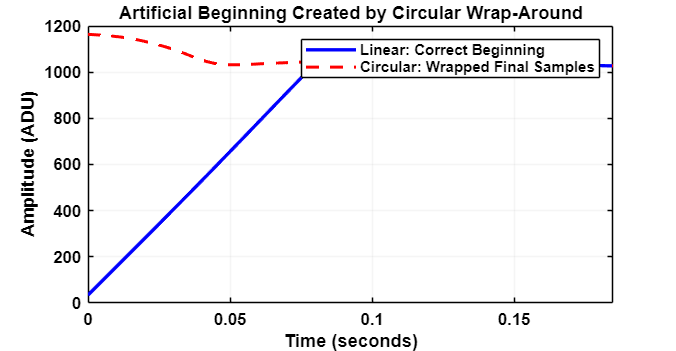

figure('Color','white', ...
       'Name','ECG Boundary Artefact', ...
       'NumberTitle','off', ...
       'Position',[150 120 1000 520]);

p3 = plot(t, yLinear, 'b', 'LineWidth', 2);
hold on;
p4 = plot(t, yCircular, 'r--', 'LineWidth', 1.8);
grid on; box on;

set(gca, 'Color','white', 'XColor','black', 'YColor','black', ...
    'GridColor',[0.75 0.75 0.75], 'FontWeight','bold');

% Zoom in on the first 0.15 seconds to see the error clearly
xlim([0 0.15]);

xlabel('Time (seconds)','FontWeight','bold');
ylabel('Amplitude (ADU)','FontWeight','bold');
title('Artificial Beginning Created by Circular Wrap-Around', 'Color','black', 'FontWeight','bold');

lgd2 = legend([p3 p4], 'Linear: Correct Beginning', 'Circular: Wrapped Final Samples', 'Location' ...
    ,'northeast');
lgd2.Color = 'white'; lgd2.TextColor = 'black'; lgd2.EdgeColor = 'black'; lgd2.FontWeight = 'bold';

## 10. BASIC R-PEAK DETECTION & HEART RATE ESTIMATION

% Feature extraction on the cleanly filtered linear signal

% Calculate a dynamic threshold relative to the baseline to avoid DC offset issues
baseline = median(yLinear);
max_val = max(yLinear);
minPeakHeight = baseline + 0.5 * (max_val - baseline); 
minPeakDist = 0.4 * Fs; % Minimum 0.4s between heartbeats (max 150 BPM)

[pks, locs] = findpeaks(yLinear, 'MinPeakHeight', minPeakHeight, 'MinPeakDistance', minPeakDist);

% Calculate RR Intervals and Heart Rate (BPM)
if length(locs) > 1
    rr_intervals = diff(locs) / Fs; % RR interval in seconds
    avg_hr = 60 / mean(rr_intervals); % Formula: 60 / RR interval
else
    rr_intervals = 0;
    avg_hr = 0;
end

fprintf('\nFEATURE EXTRACTION (EDGE NODE SIMULATION)\n');


FEATURE EXTRACTION (EDGE NODE SIMULATION)


fprintf('------------------------------------------\n');

------------------------------------------


fprintf('Detected R-Peaks           = %d\n', length(locs));

Detected R-Peaks           = 6


if avg_hr > 0
    fprintf('Average RR Interval        = %.2f seconds\n', mean(rr_intervals));
    fprintf('Estimated Heart Rate       = %.1f BPM\n', avg_hr);
else
    fprintf('Not enough peaks detected in this window to calculate BPM.\n');
end

Average RR Interval        = 1.14 seconds


Estimated Heart Rate       = 52.7 BPM


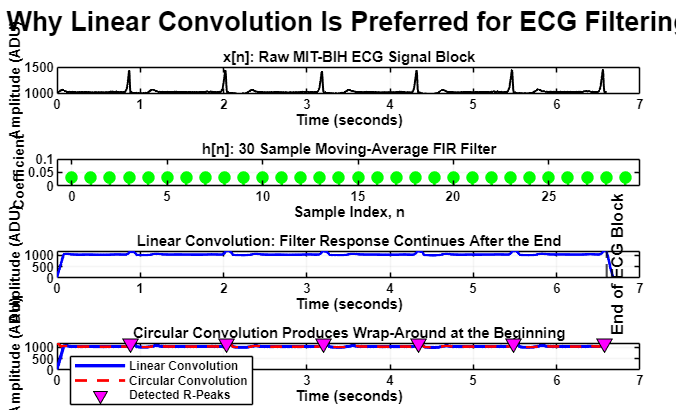


% Overlay R-peaks on Plot 4 (Linear Convolution)
figure(1);
nexttile(4); 
hold on;
plot(t(locs), pks, 'v', 'MarkerSize', 8, 'MarkerFaceColor', 'magenta', 'MarkerEdgeColor', 'black');
lgd1 = legend('Linear Convolution', 'Circular Convolution', 'Detected R-Peaks', 'Location' ...
    , 'northwest');
lgd1.Color = 'white'; lgd1.TextColor = 'black'; lgd1.EdgeColor = 'black'; lgd1.FontWeight = 'bold';